# ODE Lab: Creating your own ODE solver in MATLAB

In this lab, you will write your own ODE solver for the Improved Euler method (also known as the Heun method), and compare its results to those of `ode45`.

You will also learn how to write a function in a separate m-file and execute it.

Opening the m-file lab3.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are six (6) exercises in this lab that are to be handed in on the due date. Write your solutions in the template, including appropriate descriptions in each step. Save the .m files and submit them online on Quercus.

## Student Information

Student Name: 1008107683

Student Number: Linda Zhao

## Creating new functions using m-files.

Create a new function in a separate m-file:

Specifics: Create a text file with the file name f.m with the following lines of code (text):

Now MATLAB can call the new function f (which simply accepts 3 numbers and adds them together). To see how this works, type the following in the matlab command window: sum = f(1,2,3)

## Exercise 1

Objective: Write your own ODE solver (using the Heun/Improved Euler Method).

Details: This m-file should be a function which accepts as variables (t0,tN,y0,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0 is the initial condition of the ODE, and h is the stepsize. You may also want to pass the function into the ODE the way `ode45` does (check lab 2).

Note: you will need to use a loop to do this exercise. You will also need to recall the Heun/Improved Euler algorithm learned in lectures. 

## Exercise 2

Objective: Compare Heun with `ode45`.

Specifics: For the following initial-value problems (from lab 2, exercises 1, 4-6), approximate the solutions with your function from exercise 1 (Improved Euler Method). Plot the graphs of your Improved Euler Approximation with the `ode45` approximation.

(a) `y' = y tan t + sin t, y(0) = -1/2` from `t = 0` to `t = pi`

(b) `y' = 1 / y^2 , y(1) = 1` from `t=1` to `t=10`

(c) `y' = 1 - t y / 2, y(0) = -1` from `t=0` to `t=10`

(d) `y' = y^3 - t^2, y(0) = 1` from `t=0` to `t=1`

Comment on any major differences, or the lack thereof. You do not need to reproduce all the code here. Simply make note of any differences for each of the four IVPs.

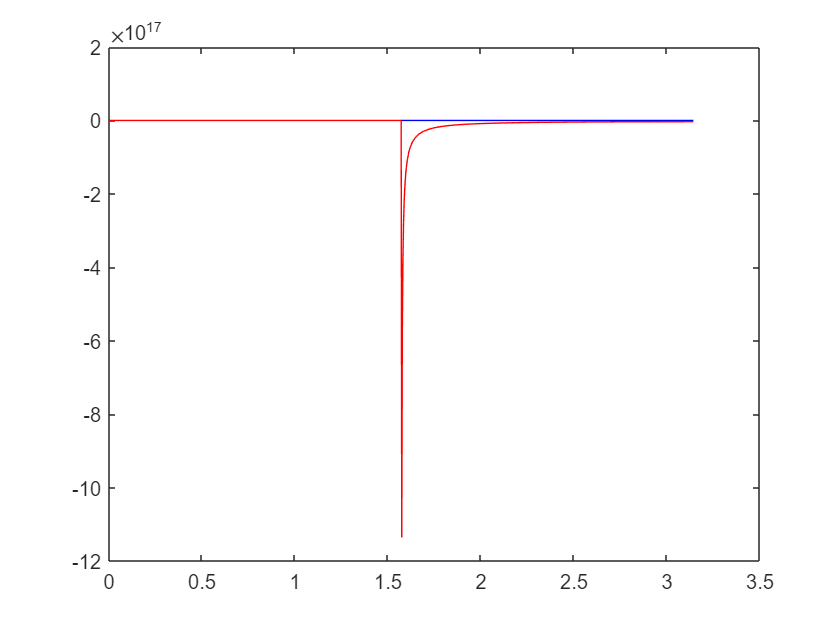

% a)
fa = @(t, y) y*tan(t) + sin(t);

t0_a = 0;
tN_a = pi;
y0_a = -0.5;

tvals = linspace(t0_a, tN_a, 1001);

a_ode45 = ode45(fa, [t0_a, tN_a], y0_a);
a_odesolver = odesolver(fa, t0_a, tN_a, y0_a, (tN_a - t0_a)/1000);

plot(a_ode45.x, a_ode45.y, 'b', tvals, a_odesolver, 'r');


% b)
fb = @(t, y) 1 / y^2

fb = function_handle with value:
    @(t,y)1/y^2


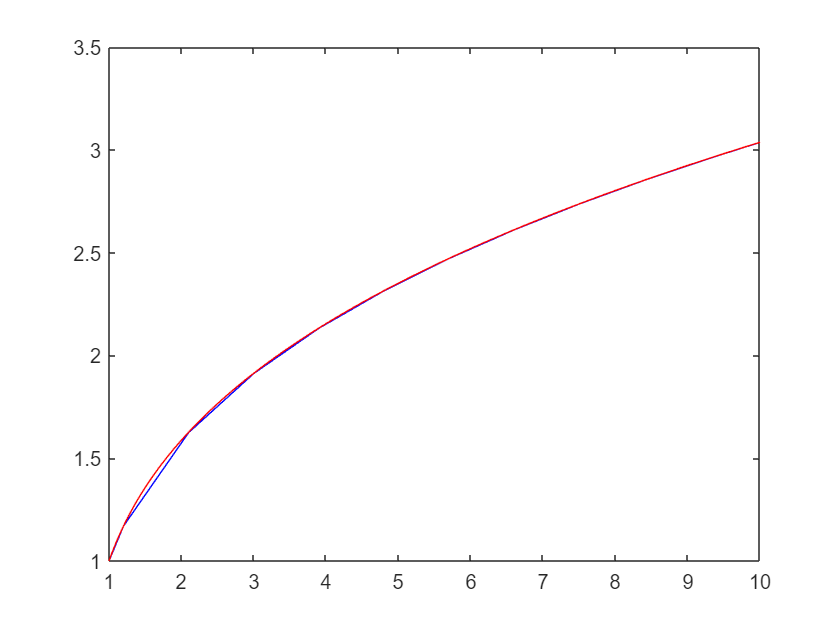


t0_b = 1;
tN_b = 10;
y0_b = 1;

tvals = linspace(t0_b, tN_b, 1001);

a_ode45 = ode45(fb, [t0_b, tN_b], y0_b);
a_odesolver = odesolver(fb, t0_b, tN_b, y0_b, (tN_b - t0_b)/1000);

plot(a_ode45.x, a_ode45.y, 'b', tvals, a_odesolver, 'r');


% c)
fc = @(t, y) 1 - t*y/2

fc = function_handle with value:
    @(t,y)1-t*y/2


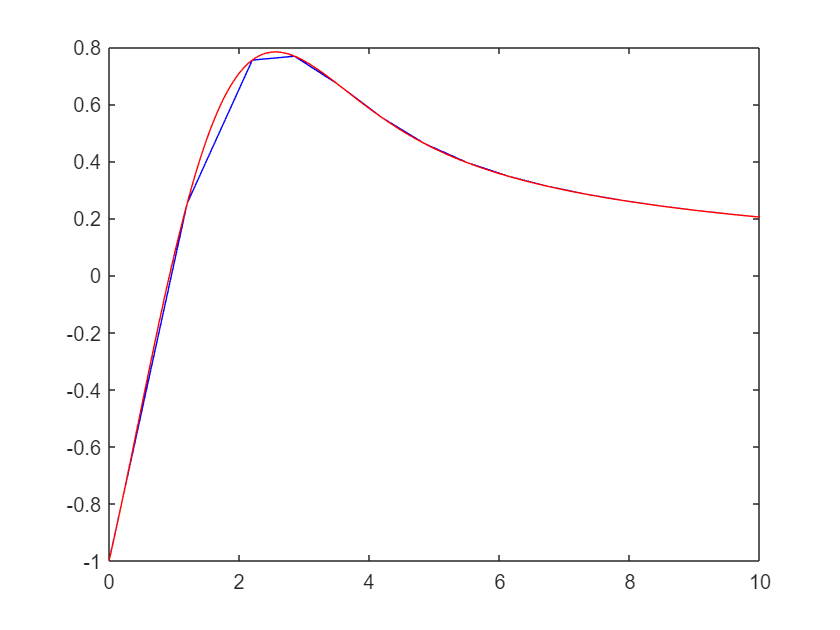


t0_c = 0;
tN_c = 10;
y0_c = -1;

tvals = linspace(t0_c, tN_c, 1001);

a_ode45 = ode45(fc, [t0_c, tN_c], y0_c);
a_odesolver = odesolver(fc, t0_c, tN_c, y0_c, (tN_c - t0_c)/1000);

plot(a_ode45.x, a_ode45.y, 'b', tvals, a_odesolver, 'r');

## Exercise 3

Objective: Use Euler's method and verify an estimate for the global error.

Details: 

(a) Use Euler's method (you can use euler.m from iode) to solve the IVP

`y' = 2 t sqrt( 1 - y^2 ) , y(0) = 0`

from `t=0` to `t=0.5`.

(b) Calculate the solution of the IVP and evaluate it at `t=0.5`.

(c) Read the attached derivation of an estimate of the global error for Euler's method. Type out the resulting bound for En here in a comment. Define each variable.

(d) Compute the error estimate for `t=0.5` and compare with the actual error.

(e) Change the time step and compare the new error estimate with the actual error. Comment on how it confirms the order of Euler's method.

## Adaptive Step Size

As mentioned in lab 2, the step size in `ode45` is adapted to a specific error tolerance.

The idea of adaptive step size is to change the step size `h` to a smaller number whenever the derivative of the solution changes quickly. This is done by evaluating f(t,y) and checking how it changes from one iteration to the next.

## Exercise 4

Objective: Create an Adaptive Euler method, with an adaptive step size `h`.

Details: Create an m-file which accepts the variables `(t0,tN,y0,h)`, as in exercise 1, where `h` is an initial step size. You may also want to pass the function into the ODE the way `ode45` does.

Create an implementation of Euler's method by modifying your solution to exercise 1. Change it to include the following:

(a) On each timestep, make two estimates of the value of the solution at the end of the timestep: `Y` from one Euler step of size `h` and `Z` from two successive Euler steps of size `h/2`. The difference in these two values is an estimate for the error.

(b) Let `tol=1e-8` and `D=Z-Y`. If `abs(D)<tol`, declare the step to be successful and set the new solution value to be `Z+D`. This value has local error `O(h^3)`. If `abs(D)>=tol`, reject this step and repeat it with a new step size, from (c).

(c) Update the step size as `h = 0.9*h*min(max(tol/abs(D),0.3),2)`.

Comment on what the formula for updating the step size is attempting to achieve.

## Exercise 5

Objective: Compare Euler to your Adaptive Euler method.

Details: Consider the IVP from exercise 3.

(a) Use Euler method to approximate the solution from `t=0` to `t=0.75` with `h=0.025`.

(b) Use your Adaptive Euler method to approximate the solution from `t=0` to `t=0.75` with initial `h=0.025`.

(c) Plot both approximations together with the exact solution.

## Exercise 6

Objective: Problems with Numerical Methods.

Details: Consider the IVP from exercise 3 (and 5).

(a) From the two approximations calculated in exercise 5, which one is closer to the actual solution (done in 3.b)? Explain why.

(b) Plot the exact solution (from exercise 3.b), the Euler's approximation (from exercise 3.a) and the adaptive Euler's approximation (from exercise 5) from `t=0` to `t=1.5`.

(c) Notice how the exact solution and the approximations become very different. Why is that? Write your answer as a comment.